clear;
% Lösung der 1D-Wellengleichung y_tt = y_xx (c^2 = 1) mit finiten
% Differenzen und Randbedingung y(rand) = 0

% Setup
t_0 = 0;                % Zeitintervall
t_max = 3;
x_0 = -1;               % Ortsintervall
x_max = 1;
dt = 0.01;              % Zeitschrittweite
dx = 0.01;              % Ortsschrittweite
n_t = t_max/dt;         % Zeitschrittzahl
n_x = (x_max - x_0)/dx; % Ortsschrittzahl


x = linspace(x_0, x_max, n_x);  % X-Grid
y = zeros(n_t, n_x);            % Init. Y-Grid

% Anfangsbedingung: Harmonische Schwingung, kann beliebig gewählt 
% werden solange konsistent mit Randbedingung
y(1, :) = 1/2*sin(6*pi*x);      
y(2, :) = 1/2*sin(6*pi*x); % 1. Zeitschritt trivial da Anfangsbedingung zeitunabhängig  

% Iteriere DGL für alle t
for j = 3:n_t
    for i = 2:n_x-1
        y(j, i) = 2*y(j-1,i) - y(j-2, i) + (dt/dx)^2 * ( y(j-1, i+1) -2*y(j-1,i) + y(j-1, i-1) );
    end 
end

% Plot
for j = 1:n_t
    plot(x, y(j,:))
    axis([-1 1 -1 1]);
    title({'Numerische L\"osung der Wellengleichung', 'f\"ur eine gespannte Saite mit harmonischer Anfangsbedingung'}, 'interpreter', 'latex')
    xlabel('$x$',"Interpreter","latex")
    ylabel('$y(x,t)$',"Interpreter","latex")
    legend(append('t = ', string(j*dt)))
    drawnow
    %movievector(j) = getframe;
end


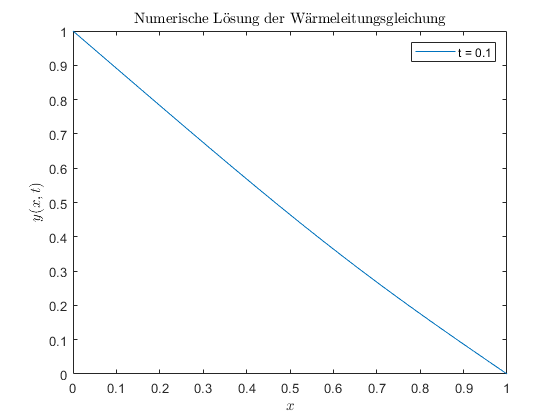

clear;
% Lösung der 1D-Diffusionsgleichung y_t = y_xx (k = 1) mit finiten
% Differenzen

% Setup
t_0 = 0;                % Zeitintervall
t_max = 0.1;
x_0 = 0;               % Ortsintervall
x_max = 1;
dt = 0.001;             % Zeitschrittweite. Beachte: dt <! dx^2/2
dx = 0.05;              % Ortsschrittweite
n_t = t_max/dt;         % Zeitschrittzahl
n_x = (x_max - x_0)/dx; % Ortsschrittzahl


x = linspace(x_0, x_max, n_x);  % X-Grid
y = zeros(n_t, n_x);            % Init. Y-Grid

% Anfangsbedingung: 
y(1, 1:n_x/2) = 1;  
y(1,n_x/2:n_x) = 0;
%y(2, :) = y(1, :);     

% Iteriere DGL für alle t
for j = 2:n_t
    y(j, 1) = 1;
    y(j, n_x) = 0;
    for i = 2:n_x-1         
        y(j, i) = y(j-1, i) + dt/dx^2 * ( y(j-1, i+1) -2*y(j-1,i) + y(j-1, i-1) );
    end 
end

% Plot
for j = 1:n_t
    plot(x, y(j,:))
    axis([0 1 0 1]);
    title({'Numerische L\"osung der W\"armeleitungsgleichung'}, 'interpreter', 'latex')
    xlabel('$x$',"Interpreter","latex")
    ylabel('$y(x,t)$',"Interpreter","latex")
    legend(append('t = ', string(j*dt)))
    drawnow
    %movievector(j) = getframe;
end


%writer = VideoWriter('Wellengleichung');
%writer.FrameRate = 30;
%open(writer);
%writeVideo(writer, movievector);
%close(writer);
